## 1D Example

% Start from here
addpath('./Skechers/');
load('./data/1DsktSample/1DsktSampleModel_small2.mat');
B_Omega = model.Omega_assemble.B; d_Omega = model.Omega_assemble.d;
B_Gamma = model.Gamma_assemble.B; d_Gamma = model.Gamma_assemble.d;
B = [B_Omega ; B_Gamma]; d = [d_Omega ; d_Gamma]; [mB, nB] = size(B); 
exact_problem.B = B; exact_problem.d = d; sparsity_threshold = 0.2;

% Solve exact problem
exact_problem.sol = solveLLS(B, d, sparsity_threshold);
exact_problem.time = timeit(@() solveLLS(B, d, sparsity_threshold));
exact_problem.sparsity = nnz(B)/(mB*nB);
exact_problem.res = norm(B*exact_problem.sol-d);
abs_error = @(x) norm(model.u(x) - model.evaluate_LSFEM_elewise(x));
exact_problem.L2 = sqrt(integral(@(x) abs_error(x).^2, model.Omega(1), model.Omega(2), 'ArrayValued', true, 'AbsTol', 1e-12));
exact_problem

% use a cell to store all the data for different sketchers
num_coworker = 50;
skt_ratios = [2,3,4,5,6,7,8,9,10]; 
sample_per_skt_coe = 20;
Sketchers = cell(1,6);       % {Gaussian, CountSketch, sHashing, LevScore, ApproxLevScore1, ApproxLevScore2};
BlockSketchers = cell(1,6);  % Block {Gaussian, CountSketch, sHashing, LevScore, ApproxLevScore1, ApproxLevScore2};

## 1D Complete Sketching

% Run model for complete sketching
% load('./data/1DsktSample/1DsktSampleResults_small_stat.mat');
[lev_score1, ~, ~] = leverageScore(B_Omega,'Exact',[],'svd'); p1 = lev_score1/sum(lev_score1);
h = waitbar(0, 'Processing...'); 
current_step = 0; total_steps = length(Sketchers) * length(skt_ratios) * sample_per_skt_coe;
for skt = 4:6
    sketcher = struct();
    for j = 1:length(skt_ratios)
        skt_ratio = skt_ratios(j); mS = round(skt_ratio*nB);
        % if (skt == 1) && (skt_ratio >=6)
        %     sketcher.sparsity(:,j) = NaN;
        %     sketcher.error(:,j) = NaN;
        %     sketcher.res(:,j) = NaN;
        %     sketcher.L2(:,j) = NaN;
        %     continue;
        % end
        for i = 1:sample_per_skt_coe

            % construct sketcher S
            if skt == 1
                [SBd, sketcher.sketch_time(i,j)] = sketching(mS, [B_Omega, d_Omega], 'Gaussian');
            elseif skt == 2
                [SBd, sketcher.sketch_time(i,j)] = sketching(mS, [B_Omega, d_Omega], 'Hashing', {1, 'Regular'});
            elseif skt == 3
                s = ceil(log(nB));
                [SBd, sketcher.sketch_time(i,j)] = sketching(mS, [B_Omega, d_Omega], 'Hashing', {s, 'Regular'});
            elseif skt == 4
                [~, ~, sketcher.lev_time(i,j)] = leverageScore(B_Omega,'Exact',[],'svd'); 
                [SBd, sketcher.sketch_time(i,j)] = sketching(mS, [B_Omega, d_Omega], 'Levscore', p1);
            elseif skt == 5
                [lev_score2, ~, sketcher.lev_time(i,j)] = leverageScore(B_Omega,'Approx',[],'svd'); 
                p2 = lev_score2/sum(lev_score2); sketcher.beta(i,j) = min(p2./p1);
                [SBd, sketcher.sketch_time(i,j)] = sketching(mS, [B_Omega, d_Omega], 'Levscore', p2);
            elseif skt == 6
                [lev_score3, ~, sketcher.lev_time(i,j)] = leverageScore(B_Omega,'Hashing_Approx',[],'svd'); 
                p3 = lev_score3/sum(lev_score3); sketcher.beta(i,j) = min(p3./p1);
                [SBd, sketcher.sketch_time(i,j)] = sketching(mS, [B_Omega, d_Omega], 'Levscore', p3);
            end

            % solve
            SBd = [SBd; [B_Gamma, d_Gamma]];
            SB = SBd(:,1:end-1); Sd = SBd(:,end);
            tic; sol = solveLLS(SB, Sd, sparsity_threshold); sketcher.solve_time(i,j) = toc;

            % other statistics
            [mm, nn] = size(SB);
            sketcher.sparsity(i,j) = nnz(SB)/(mm*nn);
            sketcher.error(i,j) = norm(sol-exact_problem.sol);
            sketcher.res(i,j) = norm(B*sol-d);

            C_skt = model.reshape2mat(sol);
            abs_error = @(x) norm(model.u(x) - model.evaluate_LSFEM_elewise(x,C_skt));
            sketcher.L2(i,j) = sqrt(integral(@(x) abs_error(x)^2, model.Omega(1), model.Omega(2), ...
                                    'ArrayValued', true, 'AbsTol', 1e-12));

            current_step = current_step + 1;
            fprintf('\n Progress: %d/%d', current_step, total_steps);
            waitbar(current_step / total_steps, h);
        end
    end
    if (skt == 1) || (skt == 2) || (skt == 3)
        sketcher.lev_time = 0;
    end
    Sketchers{skt} = sketcher;
end
close(h);
% save('./data/1DsktSample/1DsktSampleResults_small_stat.mat', 'Sketchers');

## 1D Block Sketching

% Run model for block sketching
% load('./data/1DsktSample/1DsktSampleResults_small_block_stat.mat');
h = waitbar(0, 'Processing...'); 
current_step = 0; total_steps = length(Sketchers) * length(skt_ratios) * sample_per_skt_coe;
for skt = 1:6
    sketcher = struct();
    for j = 1:length(skt_ratios)
         skt_ratio = skt_ratios(j); mS = round(skt_ratio*nB);
        for i = 1:sample_per_skt_coe

            % construct sketcher S
            if skt == 1
                [SBd, sketcher.sketch_time(i,j)] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Gaussian');
            elseif skt == 2
                [SBd, sketcher.sketch_time(i,j)] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Hashing', {1, 'Regular'});
            elseif skt == 3
                s = ceil(log(nB));
                [SBd, sketcher.sketch_time(i,j)] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Hashing', {s, 'Regular'});
            elseif skt == 4
                try
                    [SBd, sketcher.sketch_time(i,j)] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Levscore', {'Exact','svd'});
                catch
                    [SBd, sketcher.sketch_time(i,j)] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Levscore', {'Exact','svd'});
                end
            elseif skt == 5
                try
                    [SBd, sketcher.sketch_time(i,j)] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Levscore', {'Approx','svd'});
                catch
                    [SBd, sketcher.sketch_time(i,j)] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Levscore', {'Approx','svd'});
                end
            elseif skt == 6
                try
                    [SBd, sketcher.sketch_time(i,j)] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Levscore', {'Hashing_Approx','svd'});
                catch
                    [SBd, sketcher.sketch_time(i,j)] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Levscore', {'Hashing_Approx','svd'});
                end
            end

            % solve
            SBd = [SBd; [B_Gamma, d_Gamma]];
            SB = SBd(:,1:end-1); Sd = SBd(:,end);
            tic; sol = solveLLS(SB, Sd, sparsity_threshold); sketcher.solve_time(i,j) = toc;

            % other statistics
            [mm, nn] = size(SB);
            sketcher.sparsity(i,j) = nnz(SB)/(mm*nn);
            sketcher.error(i,j) = norm(sol-exact_problem.sol);
            sketcher.res(i,j) = norm(B*sol-d);

            C_skt = model.reshape2mat(sol);
            abs_error = @(x) norm(model.u(x) - model.evaluate_LSFEM_elewise(x,C_skt));
            sketcher.L2(i,j) = sqrt(integral(@(x) abs_error(x)^2, model.Omega(1), model.Omega(2), ...
                                    'ArrayValued', true, 'AbsTol', 1e-12));

            current_step = current_step + 1;
            fprintf('\n Progress: %d/%d', current_step, total_steps);
            waitbar(current_step / total_steps, h);
        end
    end
    BlockSketchers{skt} = sketcher;
end
close(h);
% save('./data/1DsktSample/1DsktSampleResults_small_block_stat.mat', 'BlockSketchers');

## 2D Example

% Start from here
addpath('./Skechers/');
load('./data/2DsktSample/2DsktSampleModel_small.mat');
B_Omega = model.Omega_assemble.B; d_Omega = model.Omega_assemble.d;
B_Gamma = model.Gamma_assemble.B; d_Gamma = model.Gamma_assemble.d;
B = [B_Omega ; B_Gamma]; d = [d_Omega ; d_Gamma]; [mB, nB] = size(B); 
exact_problem.B = B; exact_problem.d = d; sparsity_threshold = 0.2;

% Solve exact problem
exact_problem.sol = solveLLS(B, d, sparsity_threshold);
exact_problem.time = 0.9230 ; % timeit(@() solveLLS(B, d, sparsity_threshold))
exact_problem.sparsity = nnz(B)/(mB*nB);
exact_problem.res = norm(B*exact_problem.sol-d);
exact_problem.L2 = model.L2_error();
exact_problem

% use a cell to store all the data for different sketchers
num_coworker = 50;
skt_ratios = [2,3,4,5,6,7,8,9,10]; 
sample_per_skt_coe = 20;
Sketchers = cell(1,6);       % {Gaussian, CountSketch, sHashing, LevScore, ApproxLevScore1, ApproxLevScore2};
BlockSketchers = cell(1,6);  % Block {Gaussian, CountSketch, sHashing, LevScore, ApproxLevScore1, ApproxLevScore2};

## 2D Complete Sketching

% Run model for complete sketching
[lev_score1, ~, time1] = leverageScore(B_Omega,'Exact',[],'svd'); p1 = lev_score1/sum(lev_score1);
[lev_score2, ~, time2] = leverageScore(B_Omega,'Approx',[],'svd'); p2 = lev_score2/sum(lev_score2);
[lev_score3, ~, time3] = leverageScore(B_Omega,'Hashing_Approx',[],'svd'); p3 = lev_score3/sum(lev_score3);

% load('./data/2DsktSample/2DsktSampleResults_small_stat.mat');
h = waitbar(0, 'Processing...'); 
current_step = 0; total_steps = length(Sketchers) * length(skt_ratios) * sample_per_skt_coe;
for skt = 4:6
    sketcher = struct();
    for j = 1:length(skt_ratios)
        skt_ratio = skt_ratios(j); mS = round(skt_ratio*nB);
        for i = 1:sample_per_skt_coe

            % construct sketcher S
            if skt == 1
                [SBd, sketcher.sketch_time(i,j)] = sketching(mS, [B_Omega, d_Omega], 'Gaussian');
            elseif skt == 2
                [SBd, sketcher.sketch_time(i,j)] = sketching(mS, [B_Omega, d_Omega], 'Hashing', {1, 'Regular'});
            elseif skt == 3
                s = ceil(log(nB));
                [SBd, sketcher.sketch_time(i,j)] = sketching(mS, [B_Omega, d_Omega], 'Hashing', {s, 'Regular'});
            elseif skt == 4
                [SBd, sketcher.sketch_time(i,j)] = sketching(mS, [B_Omega, d_Omega], 'Levscore', p1);
            elseif skt == 5
                [SBd, sketcher.sketch_time(i,j)] = sketching(mS, [B_Omega, d_Omega], 'Levscore', p2);
            elseif skt == 6
                [SBd, sketcher.sketch_time(i,j)] = sketching(mS, [B_Omega, d_Omega], 'Levscore', p3);
            end

            % solve
            SBd = [SBd; [B_Gamma, d_Gamma]];
            SB = SBd(:,1:end-1); Sd = SBd(:,end);
            tic; sol = solveLLS(SB, Sd, sparsity_threshold); sketcher.solve_time(i,j) = toc;

            % other statistics
            [mm, nn] = size(SB);
            sketcher.sparsity(i,j) = nnz(SB)/(mm*nn);
            sketcher.error(i,j) = norm(sol-exact_problem.sol);
            sketcher.res(i,j) = norm(B*sol-d);

            C_skt = model.reshape2mat(sol);
            sketcher.L2(i,j) = model.L2_error(C_skt);

            current_step = current_step + 1;
            fprintf('\n Progress: %d/%d', current_step, total_steps);
            waitbar(current_step / total_steps, h);
        end
    end
    if (skt == 1) || (skt == 2) || (skt == 3)
        sketcher.lev_time = 0;
    elseif skt == 4
        sketcher.lev_time = time1;
        sketcher.lev_score = lev_score1;
    elseif skt == 5
        sketcher.lev_time = time2;
        sketcher.lev_score = lev_score2;
    elseif skt == 6
        sketcher.lev_time = time3;
        sketcher.lev_score = lev_score2;
    end
    Sketchers{skt} = sketcher;
end
close(h);
% save('./data/2DsktSample/2DsktSampleResults_small_stat.mat', 'Sketchers');

## 2D Block Sketching

% Run model for block sketching
load('./data/2DsktSample/2DsktSampleResults_small_block_stat.mat');
h = waitbar(0, 'Processing...'); 
current_step = 0; total_steps = length(Sketchers) * length(skt_ratios) * sample_per_skt_coe;
for skt = 4:6
    sketcher = struct();
    for j = 1:length(skt_ratios)
         skt_ratio = skt_ratios(j); mS = round(skt_ratio*nB);
        for i = 1:sample_per_skt_coe

            % construct sketcher S
            if skt == 1
                [SBd, sketcher.sketch_time(i,j)] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Gaussian');
            elseif skt == 2
                [SBd, sketcher.sketch_time(i,j)] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Hashing', {1, 'Regular'});
            elseif skt == 3
                s = ceil(log(nB));
                [SBd, sketcher.sketch_time(i,j)] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Hashing', {s, 'Regular'});
            elseif skt == 4
                try
                    [SBd, sketcher.sketch_time(i,j)] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Levscore', {'Exact','svd'});
                catch
                    [SBd, sketcher.sketch_time(i,j)] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Levscore', {'Exact','svd'});
                end
            elseif skt == 5
                try
                    [SBd, sketcher.sketch_time(i,j)] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Levscore', {'Approx','svd'});
                catch
                    [SBd, sketcher.sketch_time(i,j)] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Levscore', {'Approx','svd'});
                end
            elseif skt == 6
                try
                    [SBd, sketcher.sketch_time(i,j)] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Levscore', {'Hashing_Approx','svd'});
                catch
                    [SBd, sketcher.sketch_time(i,j)] = blockEmbedding(mS, [B_Omega, d_Omega], num_coworker, 'Levscore', {'Hashing_Approx','svd'});
                end
            end

            % solve
            SBd = [SBd; [B_Gamma, d_Gamma]];
            SB = SBd(:,1:end-1); Sd = SBd(:,end);
            tic; sol = solveLLS(SB, Sd, sparsity_threshold); sketcher.solve_time(i,j) = toc;

            % other statistics
            [mm, nn] = size(SB);
            sketcher.sparsity(i,j) = nnz(SB)/(mm*nn);
            sketcher.error(i,j) = norm(sol-exact_problem.sol);
            sketcher.res(i,j) = norm(B*sol-d);
            C_skt = model.reshape2mat(sol);
            sketcher.L2(i,j) = model.L2_error(C_skt);

            current_step = current_step + 1;
            fprintf('\n Progress: %d/%d', current_step, total_steps);
            waitbar(current_step / total_steps, h);
        end
    end
    BlockSketchers{skt} = sketcher;
end
close(h);
% save('./data/2DsktSample/2DsktSampleResults_small_block_stat.mat', 'BlockSketchers');

## 1D FEM

% Start from here
addpath('./Skechers/');
load('./data/1DsktSample/1DsktSampleModel_small.mat');
load('./data/1DsktSample/1DsktSampleResults_small_stat.mat');
load('./data/1DsktSample/1DsktSampleResults_small_block_stat.mat');
B = [model.Omega_assemble.B ; model.Gamma_assemble.B]; 
d = [model.Omega_assemble.d ; model.Gamma_assemble.d];
[mB, nB] = size(B); 
exact_problem.B = B; exact_problem.d = d;
sparsity_threshold = 0.2;

% Solve exact problem
exact_problem.sol = solveLLS(B, d, sparsity_threshold);
exact_problem.time = timeit(@() solveLLS(B, d, sparsity_threshold));
exact_problem.sparsity = nnz(B)/(mB*nB);
exact_problem.res = norm(B*exact_problem.sol-d);

abs_error = @(x) norm(model.u(x) - model.evaluate_LSFEM_elewise(x));
exact_problem.L2 = sqrt(integral(@(x) abs_error(x)^2, model.Omega(1), model.Omega(2), 'ArrayValued', true, 'AbsTol', 1e-12));
[~,S,~] = svdecon(full(B)); sigmaB = diag(S); sigmaB = sigmaB(sigmaB > 1e-6);

% use a cell to store all the data for different sketchers
num_coworker = 50; 
skt_ratios = [2,3,4,5,6,7,8,9,10]; sample_per_skt_coe = 20;
group_name = {'Gaussian', 'CountSketch', 'sHashing', 'LevScore', 'ApproxLS1', 'ApproxLS2'};
color = [0.6350,  0.0780,  0.1840; 
         0.8500,  0.3250,  0.0980; 
         247/255, 152/255, 36/255; 
         114/255, 188/255, 213/255;
         70/255,  128/255, 175/255;
         30/255,  70/255,  110/255];

sketch_time = cellfun(@(x) x.sketch_time + x.lev_time, Sketchers, 'UniformOutput', false);
solve_time = cellfun(@(x) x.solve_time, Sketchers, 'UniformOutput', false);
total_time = arrayfun(@(x) sketch_time{x} + solve_time{x}, 1:6, 'UniformOutput', false);
sparsity = cellfun(@(x) x.sparsity, Sketchers, 'UniformOutput', false);
x_error = cellfun(@(x) x.error, Sketchers, 'UniformOutput', false);
res = cellfun(@(x) x.res, Sketchers, 'UniformOutput', false);
L2 = cellfun(@(x) x.L2, Sketchers, 'UniformOutput', false);
k = cellfun(@(x) (x./exact_problem.res).^2, res, 'UniformOutput', false);
epsilon = cellfun(@(x) (x-1)./(x+1), k, 'UniformOutput', false);

sketch_time_block = cellfun(@(x) x.sketch_time, BlockSketchers, 'UniformOutput', false);
solve_time_block = cellfun(@(x) x.solve_time, BlockSketchers, 'UniformOutput', false);
total_time_block = arrayfun(@(x) sketch_time_block{x} + solve_time_block{x}, 1:6, 'UniformOutput', false);
sparsity_block = cellfun(@(x) x.sparsity, BlockSketchers, 'UniformOutput', false);
x_error_block = cellfun(@(x) x.error, BlockSketchers, 'UniformOutput', false);
res_block = cellfun(@(x) x.res, BlockSketchers, 'UniformOutput', false);
L2_block = cellfun(@(x) x.L2, BlockSketchers, 'UniformOutput', false);
k_block = cellfun(@(x) (x./exact_problem.res).^2, res_block, 'UniformOutput', false);
epsilon_block = cellfun(@(x) (x-1)./(x+1), k_block, 'UniformOutput', false);

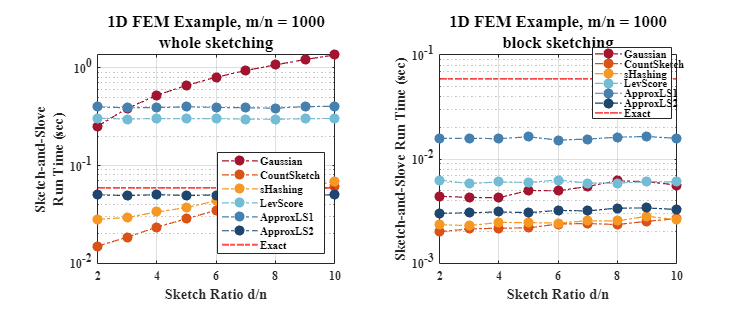

% Plot Run time
figure; set(gcf,'position',[0, 0, 1200, 500]); tiledlayout(1,2);
total_time_median = cellfun(@(x)median(x), total_time, 'UniformOutput', false);
total_time_block_median = cellfun(@(x)median(x), total_time_block, 'UniformOutput', false);

nexttile(1);
plot_lines(2:10, total_time_median, group_name, color, 'southeast');
yline(exact_problem.time, 'r-.', 'LineWidth', 1.5, 'DisplayName', 'Exact');
% ylim([0.015, 2.5]); 
ylabel({"Sketch-and-Slove"; "Run Time (sec)"},'FontSize',12); 
xlabel("Sketch Ratio d/n",'FontSize',12); 
title({'1D FEM Example, m/n = 1000';'whole sketching'},'fontweight','bold','FontSize',14)

% nexttile(3);
% plot_lines(2:10, total_time_median([2,3,6]), group_name([2,3,6]), color([2,3,6],:), 'northwest');
% yline(exact_problem.time, 'r-.', 'LineWidth', 1.5, 'DisplayName', 'Exact');
% ylim([0.004, 0.65]); 
% ylabel({"Sketch-and-Slove"; "Run Time (sec)"},'FontSize',12); 
% xlabel("Sketch Ratio d/n",'FontSize',12);

nexttile(2);
plot_lines(2:10, total_time_block_median, group_name, color, 'northeast')
yline(exact_problem.time, 'r-.', 'LineWidth', 1.5, 'DisplayName', 'Exact');
ylim([0.001, 0.1]); legend("Position", [0.79257,0.61665,0.10474,0.22926])
ylabel("Sketch-and-Slove Run Time (sec)",'FontSize',12); 
xlabel("Sketch Ratio d/n",'FontSize',12);
title({'1D FEM Example, m/n = 1000';'block sketching'},'fontweight','bold','FontSize',14)

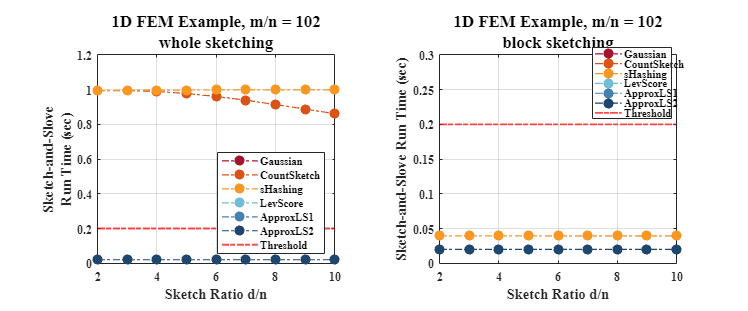

% Plot sparsity
figure; set(gcf,'position',[0, 0, 1200, 500]); tiledlayout(1,2);
sparsity_median = cellfun(@(x)median(x), sparsity, 'UniformOutput', false);
sparsity_block_median = cellfun(@(x)median(x), sparsity_block, 'UniformOutput', false);

nexttile(1);
plot_lines(2:10, sparsity_median, group_name, color, 'southeast');
yline(sparsity_threshold, 'r-.', 'LineWidth', 1.5, 'DisplayName', 'Threshold');
ylim([0, 1.2]); 
set(gca,'yscale','linear')
ylabel({"Sketch-and-Slove"; "Run Time (sec)"},'FontSize',12); 
xlabel("Sketch Ratio d/n",'FontSize',12); 
title({'1D FEM Example, m/n = 102';'whole sketching'},'fontweight','bold','FontSize',14)

nexttile(2);
plot_lines(2:10, sparsity_block_median, group_name, color, 'northeast')
yline(sparsity_threshold, 'r-.', 'LineWidth', 1.5, 'DisplayName', 'Threshold');
ylim([0, 0.3]);
set(gca,'yscale','linear')
legend("Position", [0.79257,0.61665,0.10474,0.22926])
ylabel("Sketch-and-Slove Run Time (sec)",'FontSize',12); 
xlabel("Sketch Ratio d/n",'FontSize',12);
title({'1D FEM Example, m/n = 102';'block sketching'},'fontweight','bold','FontSize',14)

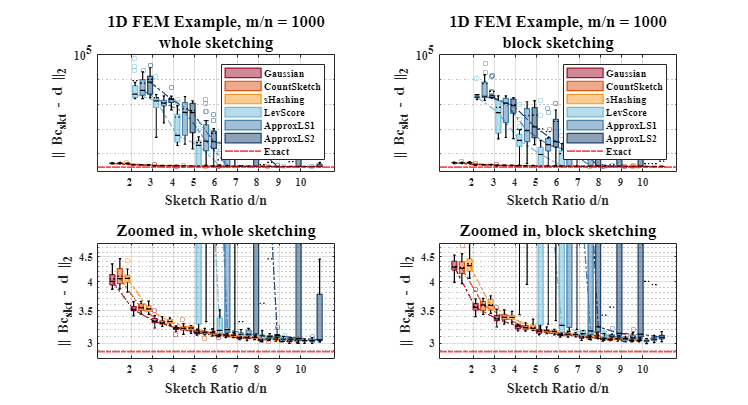

% Residual
figure; set(gcf,'position',[0, 0, 1200, 650]); tiledlayout(2,2);

nexttile(1);
p1 = simple_daboxplot(res, group_name, color);
yline(exact_problem.res, 'r-.', 'LineWidth', 1.5, 'DisplayName', 'Exact');
set(p1.lg, 'Location', 'northeast'); ylim([2, 1e5]); 
ylabel({"|| Bc_{skt} - d ||_2"},'FontSize',12); 
xlabel("Sketch Ratio d/n",'FontSize',12); 
title({'1D FEM Example, m/n = 1000';'whole sketching'},'fontweight','bold','FontSize',14)

nexttile(2);
p2 = simple_daboxplot(res_block, group_name, color);
yline(exact_problem.res, 'r-.', 'LineWidth', 1.5, 'DisplayName', 'Exact');
set(p2.lg, 'Location', 'northeast'); ylim([2, 1e5]); 
ylabel("|| Bc_{skt} - d ||_2",'FontSize',12); 
xlabel("Sketch Ratio d/n",'FontSize',12);
title({'1D FEM Example, m/n = 1000';'block sketching'},'fontweight','bold','FontSize',14)

nexttile(3);
p3 = simple_daboxplot(res, group_name, color);
yline(exact_problem.res, 'r-.', 'LineWidth', 1.5, 'DisplayName', 'Exact');
ylim([2.8, 4.8]); legend off; 
ylabel({"|| Bc_{skt} - d ||_2"},'FontSize',12); 
xlabel("Sketch Ratio d/n",'FontSize',12); 
title({'Zoomed in, whole sketching'},'fontweight','bold','FontSize',14)

nexttile(4);+
p4 = simple_daboxplot(res_block, group_name, color);
yline(exact_problem.res, 'r-.', 'LineWidth', 1.5, 'DisplayName', 'Exact');
ylim([2.8, 4.8]); legend off;  
ylabel("|| Bc_{skt} - d ||_2",'FontSize',12); 
xlabel("Sketch Ratio d/n",'FontSize',12);
title({'Zoomed in, block sketching'},'fontweight','bold','FontSize',14)

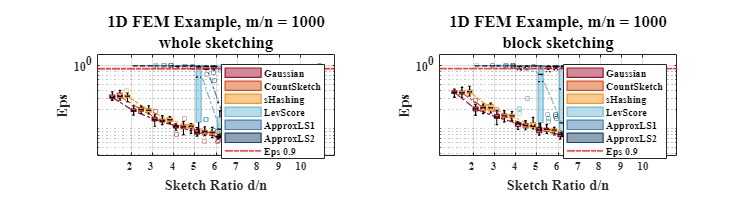

% eps
figure; set(gcf,'position',[0, 0, 1200, 325]); tiledlayout(1,2);

nexttile(1);
p1 = simple_daboxplot(epsilon, group_name, color);
yline(0.9, 'r-.', 'LineWidth', 1.5, 'DisplayName', 'Eps 0.9');
set(p1.lg, 'Location', 'northeast'); ylim([0, 1.5]);
ylabel({"Eps"},'FontSize',12); 
xlabel("Sketch Ratio d/n",'FontSize',12); 
title({'1D FEM Example, m/n = 1000';'whole sketching'},'fontweight','bold','FontSize',14)

nexttile(2);
p2 = simple_daboxplot(epsilon_block, group_name, color);
yline(0.9, 'r-.', 'LineWidth', 1.5, 'DisplayName', 'Eps 0.9');
set(p2.lg, 'Location', 'northeast'); ylim([0, 1.5]);
ylabel("Eps",'FontSize',12); 
xlabel("Sketch Ratio d/n",'FontSize',12);
title({'1D FEM Example, m/n = 1000';'block sketching'},'fontweight','bold','FontSize',14)

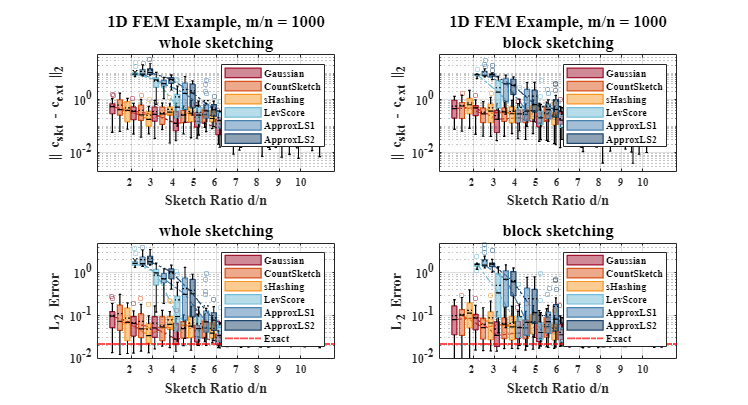

% x_error and L2
figure; set(gcf,'position',[0, 0, 1200, 650]); tiledlayout(2,2);
upperb = 20 / min(sigmaB) *  exact_problem.res; % 1.6266

nexttile(1);
p1 = simple_daboxplot(x_error, group_name, color);
% yline(upperb, 'r-.', 'LineWidth', 1.5, 'DisplayName', 'EstBound 1.6');
ylim([0.002, 50]); set(p1.lg, 'Location', 'northeast'); 
ylabel({"|| c_{skt} - c_{ext} ||_2"},'FontSize',12); 
xlabel("Sketch Ratio d/n",'FontSize',12); 
title({'1D FEM Example, m/n = 1000';'whole sketching'},'fontweight','bold','FontSize',14)

nexttile(2);
p2 = simple_daboxplot(x_error_block, group_name, color);
% yline(upperb, 'r-.', 'LineWidth', 1.5, 'DisplayName', 'EstBound 1.6');
ylim([0.002, 50]); set(p2.lg, 'Location', 'northeast'); 
ylabel("|| c_{skt} - c_{ext} ||_2",'FontSize',12); 
xlabel("Sketch Ratio d/n",'FontSize',12);
title({'1D FEM Example, m/n = 1000';'block sketching'},'fontweight','bold','FontSize',14)

nexttile(3);
p3 = simple_daboxplot(L2, group_name, color);
yline(exact_problem.L2, 'r-.', 'LineWidth', 1.5, 'DisplayName', 'Exact');
ylim([1e-2, 5]); set(p3.lg, 'Location', 'northeast'); 
ylabel({"L_2 Error"},'FontSize',12); 
xlabel("Sketch Ratio d/n",'FontSize',12); 
title({'whole sketching'},'fontweight','bold','FontSize',14)

nexttile(4);
p4 = simple_daboxplot(L2_block, group_name, color);
yline(exact_problem.L2, 'r-.', 'LineWidth', 1.5, 'DisplayName', 'Exact');
ylim([1e-2, 5]); set(p4.lg, 'Location', 'northeast'); 
ylabel("L_2 Error",'FontSize',12); 
xlabel("Sketch Ratio d/n",'FontSize',12);
title({'block sketching'},'fontweight','bold','FontSize',14);

## 2D FEM

% Start from here
addpath('./Skechers/');
load('./data/2DsktSample/2DsktSampleModel_small.mat');
load('./data/2DsktSample/2DsktSampleResults_small_stat.mat');
load('./data/2DsktSample/2DsktSampleResults_small_block_stat.mat');
B_Omega = model.Omega_assemble.B; d_Omega = model.Omega_assemble.d;
B_Gamma = model.Gamma_assemble.B; d_Gamma = model.Gamma_assemble.d;
B = [B_Omega ; B_Gamma]; d = [d_Omega ; d_Gamma]; [mB, nB] = size(B); 
exact_problem.B = B; exact_problem.d = d; sparsity_threshold = 0.2;

% Solve exact problem
exact_problem.sol = solveLLS(B, d, sparsity_threshold);
exact_problem.time = 0.9230 ; % timeit(@() solveLLS(B, d, sparsity_threshold))
exact_problem.sparsity = nnz(B)/(mB*nB);
exact_problem.res = norm(B*exact_problem.sol-d);
exact_problem.L2 = model.L2_error();
[~,S,~] = svdecon(full(B)); sigmaB = diag(S); sigmaB = sigmaB(sigmaB > 1e-6);
exact_problem

exact_problem = 包含以下字段的 struct :
           B: [252216×1101 double]
           d: [252216×1 double]
         sol: [1101×1 double]
        time: 0.9230
    sparsity: 0.0054
         res: 130.3824
          L2: 0.0463


% use a cell to store all the data for different sketchers
num_coworker = 50; 
skt_ratios = [2,3,4,5,6,7,8,9,10]; sample_per_skt_coe = 20;
group_name = {'Gaussian', 'CountSketch', 'sHashing', 'LevScore', 'ApproxLS1', 'ApproxLS2'};
color = [0.6350,  0.0780,  0.1840; 
         0.8500,  0.3250,  0.0980; 
         247/255, 152/255, 36/255; 
         114/255, 188/255, 213/255;
         70/255,  128/255, 175/255;
         30/255,  70/255,  110/255];

sketch_time = cellfun(@(x) x.sketch_time + x.lev_time, Sketchers, 'UniformOutput', false);
solve_time = cellfun(@(x) x.solve_time, Sketchers, 'UniformOutput', false);
total_time = arrayfun(@(x) sketch_time{x} + solve_time{x}, 1:6, 'UniformOutput', false);
sparsity = cellfun(@(x) x.sparsity, Sketchers, 'UniformOutput', false);
x_error = cellfun(@(x) x.error, Sketchers, 'UniformOutput', false);
res = cellfun(@(x) x.res, Sketchers, 'UniformOutput', false);
L2 = cellfun(@(x) x.L2, Sketchers, 'UniformOutput', false);
k = cellfun(@(x) (x./exact_problem.res).^2, res, 'UniformOutput', false);
epsilon = cellfun(@(x) (x-1)./(x+1), k, 'UniformOutput', false);

sketch_time_block = cellfun(@(x) x.sketch_time, BlockSketchers, 'UniformOutput', false);
solve_time_block = cellfun(@(x) x.solve_time, BlockSketchers, 'UniformOutput', false);
total_time_block = arrayfun(@(x) sketch_time_block{x} + solve_time_block{x}, 1:6, 'UniformOutput', false);
sparsity_block = cellfun(@(x) x.sparsity, BlockSketchers, 'UniformOutput', false);
x_error_block = cellfun(@(x) x.error, BlockSketchers, 'UniformOutput', false);
res_block = cellfun(@(x) x.res, BlockSketchers, 'UniformOutput', false);
L2_block = cellfun(@(x) x.L2, BlockSketchers, 'UniformOutput', false);
k_block = cellfun(@(x) (x./exact_problem.res).^2, res_block, 'UniformOutput', false);
epsilon_block = cellfun(@(x) (x-1)./(x+1), k_block, 'UniformOutput', false);

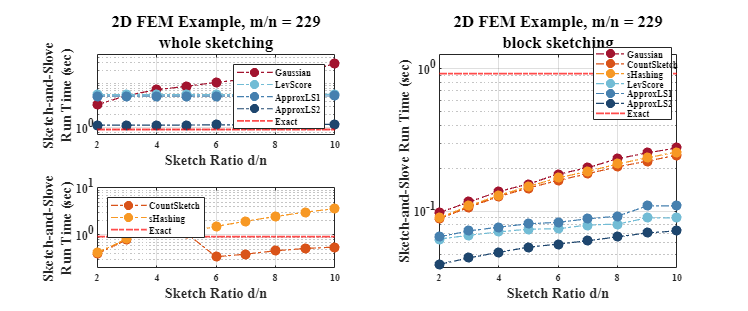

% Plot Run time
figure; set(gcf,'position',[0, 0, 1200, 500]); tiledlayout(2,2);
total_time_median = cellfun(@(x)median(x), total_time, 'UniformOutput', false);
total_time_block_median = cellfun(@(x)median(x), total_time_block, 'UniformOutput', false);

nexttile(1);
plot_lines(2:10, total_time_median([1,4,5,6]), group_name([1,4,5,6]), color([1,4,5,6],:), 'northeast');
yline(exact_problem.time, 'r-.', 'LineWidth', 1.5, 'DisplayName', 'Exact');
ylim([0.7, 45]); 
ylabel({"Sketch-and-Slove"; "Run Time (sec)"},'FontSize',12); 
xlabel("Sketch Ratio d/n",'FontSize',12); 
title({'2D FEM Example, m/n = 229';'whole sketching'},'fontweight','bold','FontSize',14)

nexttile(3);
plot_lines(2:10, total_time_median([2,3]), group_name([2,3]), color([2,3],:), 'northwest');
yline(exact_problem.time, 'r-.', 'LineWidth', 1.5, 'DisplayName', 'Exact');
ylim([0.2, 10]); 
ylabel({"Sketch-and-Slove"; "Run Time (sec)"},'FontSize',12); 
xlabel("Sketch Ratio d/n",'FontSize',12);

nexttile(2, [2,1]);
plot_lines(2:10, total_time_block_median, group_name, color, 'northeast')
yline(exact_problem.time, 'r-.', 'LineWidth', 1.5, 'DisplayName', 'Exact');
ylim([0.04, 1.25]); legend("Position", [0.79257,0.61665,0.10474,0.22926])
ylabel("Sketch-and-Slove Run Time (sec)",'FontSize',12); 
xlabel("Sketch Ratio d/n",'FontSize',12);
title({'2D FEM Example, m/n = 229';'block sketching'},'fontweight','bold','FontSize',14)

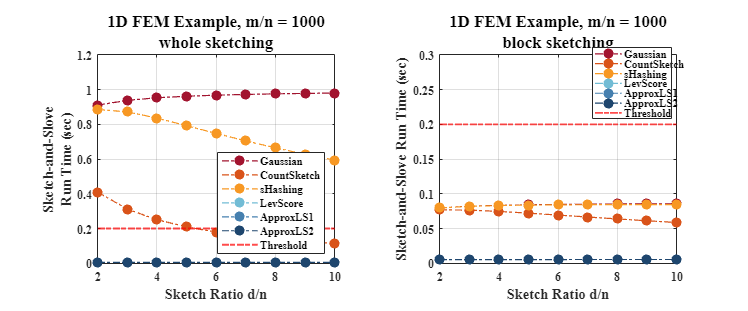

% Plot sparsity
figure; set(gcf,'position',[0, 0, 1200, 500]); tiledlayout(1,2);
sparsity_median = cellfun(@(x)median(x), sparsity, 'UniformOutput', false);
sparsity_block_median = cellfun(@(x)median(x), sparsity_block, 'UniformOutput', false);

nexttile(1);
plot_lines(2:10, sparsity_median, group_name, color, 'southeast');
yline(sparsity_threshold, 'r-.', 'LineWidth', 1.5, 'DisplayName', 'Threshold');
ylim([0, 1.2]); 
set(gca,'yscale','linear')
ylabel({"Sketch-and-Slove"; "Run Time (sec)"},'FontSize',12); 
xlabel("Sketch Ratio d/n",'FontSize',12); 
title({'1D FEM Example, m/n = 1000';'whole sketching'},'fontweight','bold','FontSize',14)

nexttile(2);
plot_lines(2:10, sparsity_block_median, group_name, color, 'northeast')
yline(sparsity_threshold, 'r-.', 'LineWidth', 1.5, 'DisplayName', 'Threshold');
ylim([0, 0.3]);
set(gca,'yscale','linear')
legend("Position", [0.79257,0.61665,0.10474,0.22926])
ylabel("Sketch-and-Slove Run Time (sec)",'FontSize',12); 
xlabel("Sketch Ratio d/n",'FontSize',12);
title({'1D FEM Example, m/n = 1000';'block sketching'},'fontweight','bold','FontSize',14)

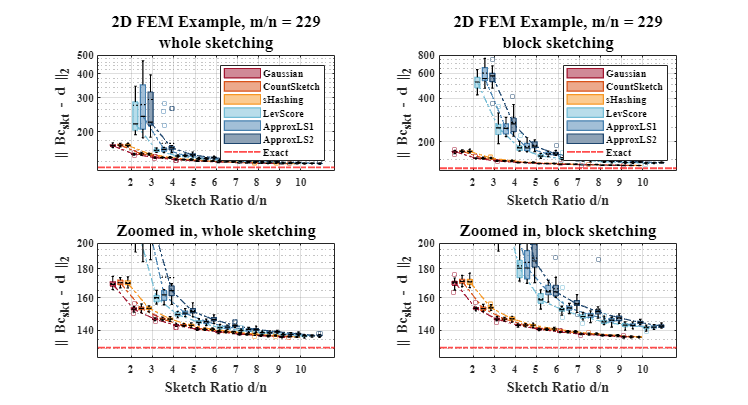

% Residual
figure; set(gcf,'position',[0, 0, 1200, 650]); tiledlayout(2,2);

nexttile(1);
p1 = simple_daboxplot(res, group_name, color);
yline(exact_problem.res, 'r-.', 'LineWidth', 1.5, 'DisplayName', 'Exact');
ylim([125, 500]), set(p1.lg, 'Location', 'northeast'); 
ylabel({"|| Bc_{skt} - d ||_2"},'FontSize',12); 
xlabel("Sketch Ratio d/n",'FontSize',12); 
title({'2D FEM Example, m/n = 229';'whole sketching'},'fontweight','bold','FontSize',14)

nexttile(2);
p2 = simple_daboxplot(res_block, group_name, color);
yline(exact_problem.res, 'r-.', 'LineWidth', 1.5, 'DisplayName', 'Exact');
ylim([125, 800]); set(p2.lg, 'Location', 'northeast'); 
ylabel("|| Bc_{skt} - d ||_2",'FontSize',12); 
xlabel("Sketch Ratio d/n",'FontSize',12);
title({'2D FEM Example, m/n = 229';'block sketching'},'fontweight','bold','FontSize',14)

nexttile(3);
p3 = simple_daboxplot(res, group_name, color);
yline(exact_problem.res, 'r-.', 'LineWidth', 1.5, 'DisplayName', 'Exact');
ylim([125, 200]);  legend off;  
ylabel("|| Bc_{skt} - d ||_2",'FontSize',12); 
xlabel("Sketch Ratio d/n",'FontSize',12);
title({'Zoomed in, whole sketching'},'fontweight','bold','FontSize',14)

nexttile(4);
p4 = simple_daboxplot(res_block, group_name, color);
yline(exact_problem.res, 'r-.', 'LineWidth', 1.5, 'DisplayName', 'Exact');
ylim([125, 200]);  legend off;  
ylabel("|| Bc_{skt} - d ||_2",'FontSize',12); 
xlabel("Sketch Ratio d/n",'FontSize',12);
title({'Zoomed in, block sketching'},'fontweight','bold','FontSize',14)

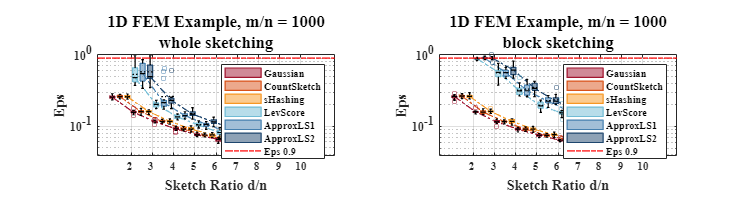

% eps
figure; set(gcf,'position',[0, 0, 1200, 325]); tiledlayout(1,2);

nexttile(1);
p1 = simple_daboxplot(epsilon, group_name, color);
yline(0.9, 'r-.', 'LineWidth', 1.5, 'DisplayName', 'Eps 0.9');
set(p1.lg, 'Location', 'northeast'); ylim([0, 1]);
ylabel({"Eps"},'FontSize',12); 
xlabel("Sketch Ratio d/n",'FontSize',12); 
title({'1D FEM Example, m/n = 1000';'whole sketching'},'fontweight','bold','FontSize',14)

nexttile(2);
p2 = simple_daboxplot(epsilon_block, group_name, color);
yline(0.9, 'r-.', 'LineWidth', 1.5, 'DisplayName', 'Eps 0.9');
set(p2.lg, 'Location', 'northeast'); ylim([0, 1]);
ylabel("Eps",'FontSize',12); 
xlabel("Sketch Ratio d/n",'FontSize',12);
title({'1D FEM Example, m/n = 1000';'block sketching'},'fontweight','bold','FontSize',14)

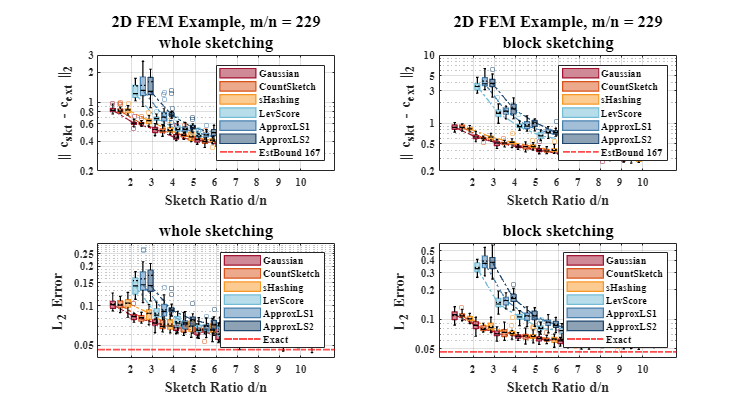

% x_error and L2
figure; set(gcf,'position',[0, 0, 1200, 650]); tiledlayout(2,2);
upperb = 20 / min(sigmaB) *  exact_problem.res; % 167

nexttile(1);
p1 = simple_daboxplot(x_error, group_name, color);
yline(upperb, 'r-.', 'LineWidth', 1.5, 'DisplayName', 'EstBound 167');
ylim([0.2, 3]);  set(p1.lg, 'Location', 'northeast'); set(gca,'YTick',[0.2,0.4,0.6,0.8,1,2,3]); 
ylabel({"|| c_{skt} - c_{ext} ||_2"},'FontSize',12); 
xlabel("Sketch Ratio d/n",'FontSize',12); 
title({'2D FEM Example, m/n = 229';'whole sketching'},'fontweight','bold','FontSize',14)

nexttile(2);
p2 = simple_daboxplot(x_error_block, group_name, color);
yline(upperb, 'r-.', 'LineWidth', 1.5, 'DisplayName', 'EstBound 167');
ylim([0.2, 10]); set(p2.lg, 'Location', 'northeast'); set(gca,'YTick',[0.2,0.5,1,3,5,10]);
ylabel("|| c_{skt} - c_{ext} ||_2",'FontSize',12); 
xlabel("Sketch Ratio d/n",'FontSize',12);
title({'2D FEM Example, m/n = 229';'block sketching'},'fontweight','bold','FontSize',14)

nexttile(3);
p3 = simple_daboxplot(L2, group_name, color);
yline(exact_problem.L2, 'r-.', 'LineWidth', 1.5, 'DisplayName', 'Exact');
ylim([0.04, 0.3]); set(p3.lg, 'Location', 'northeast'); 
ylabel({"L_2 Error"},'FontSize',12); 
xlabel("Sketch Ratio d/n",'FontSize',12); 
title({'whole sketching'},'fontweight','bold','FontSize',14)

nexttile(4);
p4 = simple_daboxplot(L2_block, group_name, color);
yline(exact_problem.L2, 'r-.', 'LineWidth', 1.5, 'DisplayName', 'Exact');
ylim([0.04, 0.6]); set(p4.lg, 'Location', 'northeast'); set(gca,'YTick',[0.05,0.1,0.2,0.3,0.4,0.5]);
ylabel("L_2 Error",'FontSize',12); 
xlabel("Sketch Ratio d/n",'FontSize',12);
title({'block sketching'},'fontweight','bold','FontSize',14);

function h = simple_daboxplot(data, group_name, color, xtlabels)
    arguments
        data
        group_name
        color
        xtlabels = 2:10
    end

    h = daboxplot( data, 'fill', 1, 'linkline', 1, 'legend', group_name, ...
              'boxalpha', 0.5,'mean', 1, 'scatter', 0, 'outliers', 1, 'outsymbol', 'o', ...
              'boxwidth', 2.5, 'boxspacing', 1.5, 'colors', color, 'xtlabels' , xtlabels);
    for i = 1:length(group_name)
        hScatter = h.ot(:,i);
        for j = 1:length(hScatter) 
            set(h.ot(j,i), 'CData', color(i,:));
            set(h.bx(j,i), 'LineWidth', 1, 'EdgeColor', color(i,:));
        end
    end
    set(h.ln, 'LineStyle', '-.', 'LineWidth', 1);
    set(h.md, 'LineWidth', 1);
    set(h.mn, 'LineWidth', 1);
    box on; grid on;
    set(gca, 'YScale', 'log');
    set(gca,'fontname','times','FontWeight','Bold');
end

function plot_lines(x, Ydata, group_name, color, legend_loc)
    arguments
        x
        Ydata % cell
        group_name
        color
        legend_loc = 'southeast'
     end

    for i = 1:length(Ydata)
        l = length(Ydata{i});
    plot( x(1:l), Ydata{i}, 'Marker', '.', 'MarkerSize', 25, ...
        'LineStyle', '-.', 'LineWidth', 1, 'Color', color(i,:), ...
        'DisplayName',group_name{i});
    hold on
    end
    box on; grid on; legend('Location', legend_loc);
    set(gca, 'YScale', 'log');
    set(gca,'fontname','times','FontWeight','Bold');
    hold off
end